# Scripts Fonctions de transfert

clear;clc;close all;
format shorteng; format compact;


Constantes

Kp = -1;


Définition de la fonction de transfert

num = [3, 6];
den = [12, (3*Kp+12), 6*Kp];
sys = tf(num, den)

sys =
 
      3 s + 6
  ----------------
  12 s^2 + 9 s - 6
 
Continuous-time transfer function.



Transformée inverse (besoin d'un addon "Inverse Laplace Transform of Transfer Function Class")

ilaplacetf(sys)

$$ans = \frac{{\mathrm{e}}^{-\frac{3\,t}{8}}\,\left(\cosh\left(\frac{\sqrt{41}\,t}{8}\right)+\frac{13\,\sqrt{41}\,\sinh\left(\frac{\sqrt{41}\,t}{8}\right)}{41}\right)}{4}$$

## Décomposer en fractions partielles

Utilisé pour faire Laplace inverse

... = r1/p1 + r2/p2 + r3/p3 + k

[r p k] = residue(num, den)

r =   -128.7824e-003
   378.7824e-003


p =     -1.1754e+000
   425.3905e-003


k =
     []


## Esquisser la réponse indicielle

à un saut unité

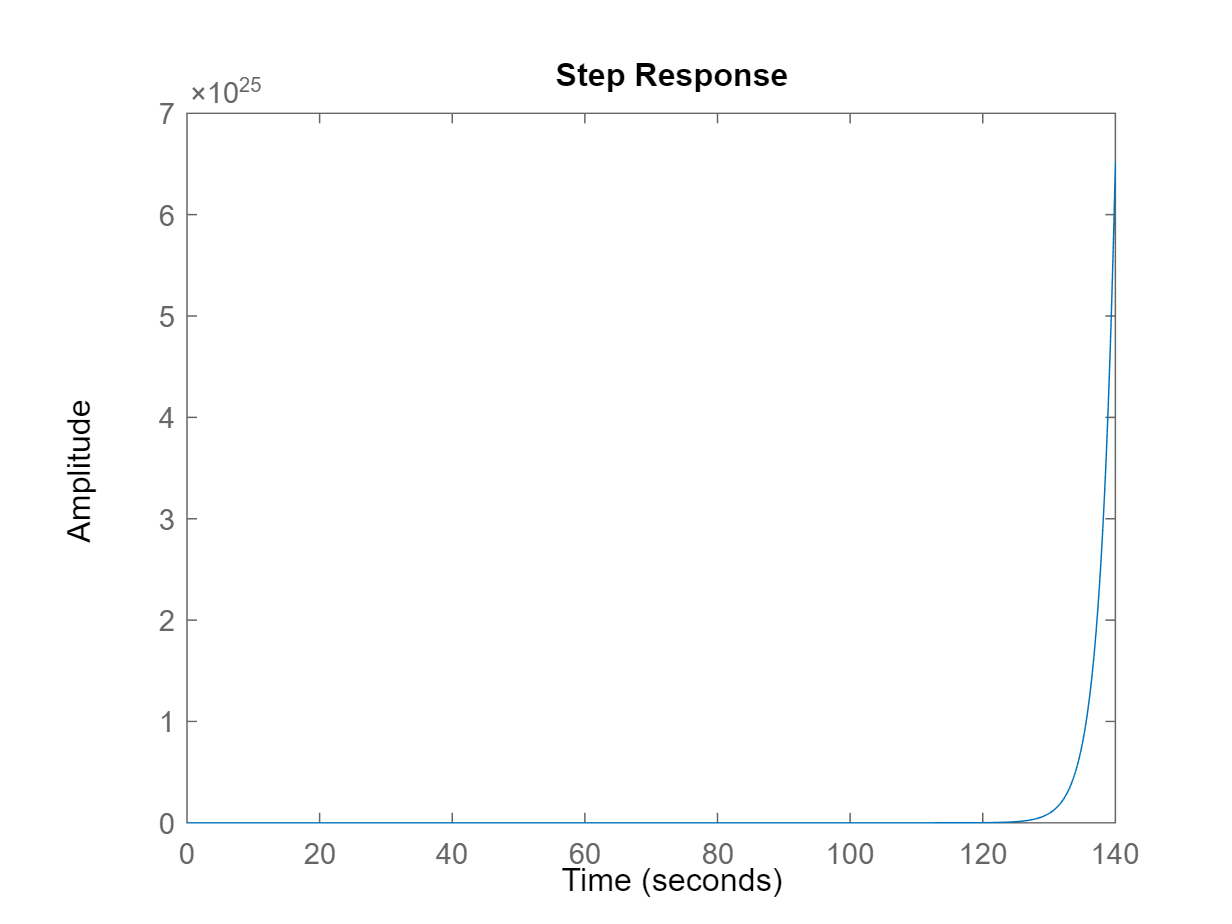

step(sys);

## Esquisser la réponse impulsionnelle

à une impulsion de dirac

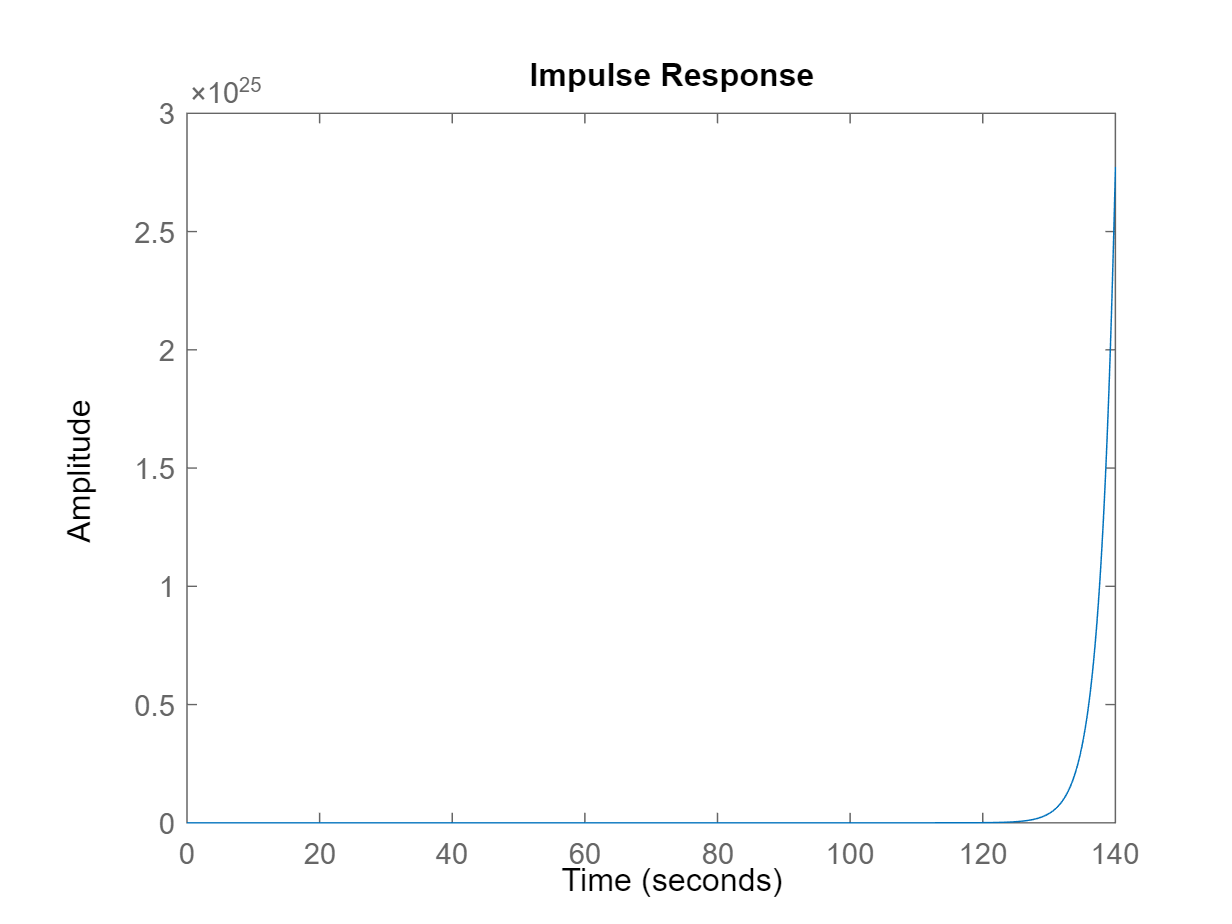

impulse(sys);

## Calculer les pôles

poles = pole(sys)

poles =     -1.1754e+000
   425.3905e-003


## Pulsation naturelle

Si conjugués complexes

omega_0 = abs(poles(1)) % Norme

omega_0 =      1.1754e+000

Si non conjugués complexes

omega_0 = sqrt(poles(1) * poles(2))

omega_0 =      0.0000e+000 +707.1068e-003i

## Facteur d'amortissement

Si conjugués complexes

xi = - real(poles(1)) / omega_0

xi =      0.0000e+000 -  1.6623e+000i

Si non conjugués complexes

xi = - (poles(1) + poles(2))/(2*omega_0)

xi =      0.0000e+000 -530.3301e-003i

## Pulsation de résonnance

Si conjugués complexes

omega_r = abs(imag(poles(1)))

omega_r =      0.0000e+000

Si non conjugués complexes

omega_r = omega_0 * sqrt(1-xi^2)

omega_r =      0.0000e+000 +800.3905e-003i